# Mass spring damper model

This script solves the second-order [**linear differential equation**](https://en.wikipedia.org/wiki/Linear_differential_equation) of a commonly used mass-spring-damper model in engineering practice to examine the vibration comfort parameters of a vehicle. A differential equation of order $n$ is linear if it has the following form:


$$a_0(t)x(t) + a_1(t) \dot x(t) + a_2(t) \ddot x(t) + ... 
+ a_n(t) x^{(n)}(t) = b(t)$$


The mass-spring-damper model is illustrated by the following figure.

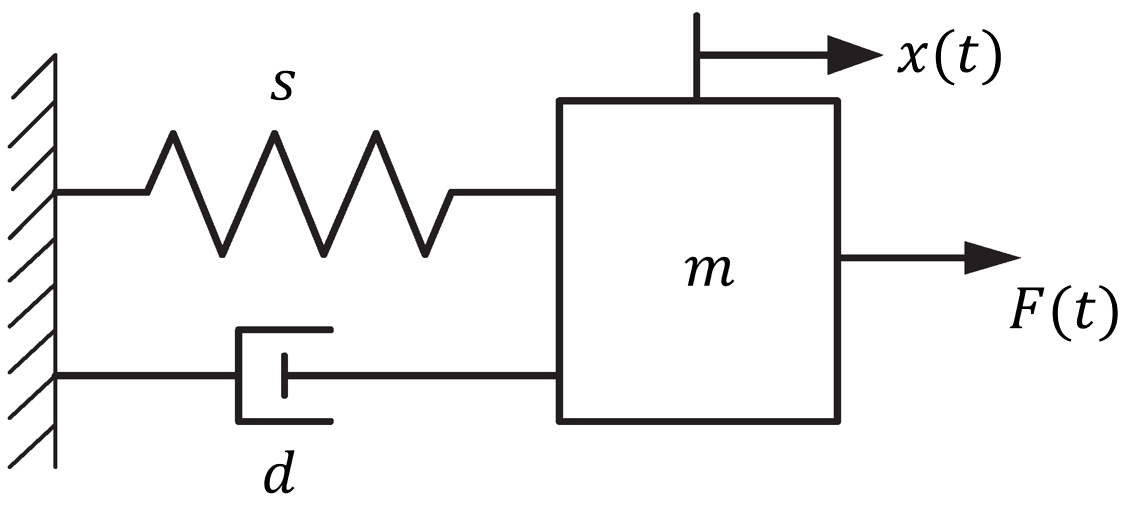

The second-order differential equation of the mass-spring-damper model is given according to the Newton's second law.

$m \ddot x(t) + d \dot x(t) + sx(t) = F(t)$.

The independent time variable $t$ is neglected from now on. The equation can be given in an explicit form as follows:


$$\ddot x = \frac{F - d \dot x - sx}{m}$$


Let $X$ denote the state vector of the model containing the $x$ displacement and its $\dot x$ first derivative as:


$$X = \left[ \matrix{ x \cr \dot x} \right], \quad
\dot X =  \left[ \matrix{\dot x \cr \ddot x} \right]$$


Since, the $m,s,d$ model parameters (coefficients of the derivatives) are constants, the second-order linear equation, can be formed to a first-order, linear, time-invariant equation system:


$$\dot X = \mathbf{A}\cdot X + \mathbf{B} \cdot u = 
\left[ \matrix{0 & 1 \cr -\frac{s}{m} & -\frac{d}{m}} \right] \left[ \matrix{x \cr \dot x} \right] + \left[ \matrix{0 \cr \frac{1}{m}} \right] F$$


where $\mathbf{A}$, $\mathbf{B}$ denote the transition and control matrices and $u$ is the model input.

## Loading model parameters and input

The parameters of the model and the input is pre-created in a separate [`creatingInputForMds`](matlab:open('./creatinginputformds')) script.

modelInput = load('mdsInput.mat');
modelParams = load('modelParams');

## Solving the linear differential equation

### Initial condition 

X0 = [0;   % initial velocity [m/s]
      0.1];  % initial position [m]

### Time interval for the "simulation"

timeSpan = [0, 15]; % [s]

### Solver

[timeVect, XMat] = ode45(@(t,X) massDamperSpringEquation (t, X, modelParams, modelInput), ...
    modelInput.timeVect, X0);

## Results

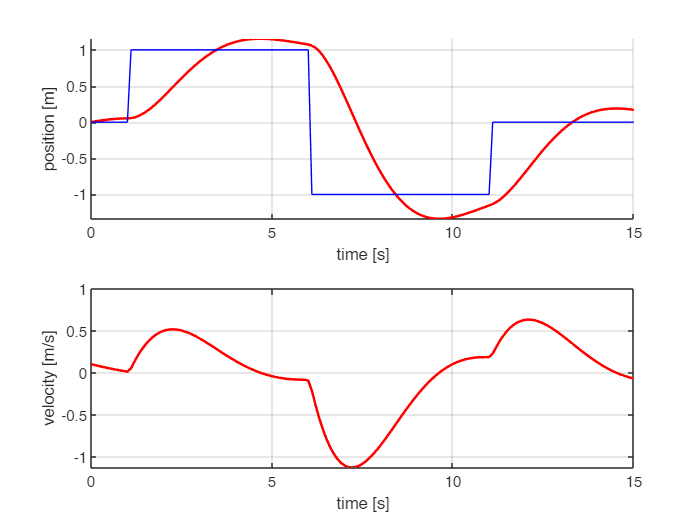

fig = figure('Color', 'white');

ax1 = axes(fig);
subplot(2, 1, 1, ax1);
hold(ax1, 'on')
plot(ax1, timeVect, XMat(:, 1), 'r-', 'LineWidth', 1.5);
plot(ax1, modelInput.timeVect, modelInput.inputVect, 'blue')
hold(ax1, 'off')
ylabel(ax1, 'position [m]');
xlabel(ax1, 'time [s]');
grid(ax1, 'on');

ax2 = axes(fig);
subplot(2, 1, 2, ax2);
plot(ax2, timeVect, XMat(:, 2), 'r-', 'LineWidth', 1.5);
ylabel(ax2, 'velocity [m/s]');
xlabel(ax2, 'time [s]');
grid(ax2, 'on');